# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

## 实验九 期末综合实验

## 一、实验目的

- 利用Windows下的录音机设备录制一段音乐信号。

- 得到加噪后的音乐信号。

- 设计LMS滤波器滤除噪声。

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验任务，认真、详实地书写实验报告，展示自己的思考过程、解题思路、理论原理、实验过程。简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

### **LMS滤波算法：**

          最小均方(Least Mean Square，LMS)算法使用随机梯度下降的方法实现代价函数的最小化，具有计算复杂度低、无需统计数据的先验知识和均值无偏地收敛到维纳解等优点，成为自适应算法中应用最广泛的一种。

          对于输入信号$x\left(n\right)$，其通过参数可调的横向滤波器后，输出为$y\left(n\right)$，LMS算法根据滤波器的输出信号$y\left(n\right)$与期望信号$d\left(n\right)$的误差自动地调整滤波器的参数，从而使得滤波器适应随机信号的时变统计特性。

          其计算步骤为：

          1.设输入信号为向量$X{\left(n\right)}={\left\lbrack x\left(n\right),x\left(n-1\right),\ldotp \ldotp \ldotp ,x\left(n-L\right)\right\rbrack }^T$，LMS自适应滤波器的输出为$y\left(n\right)$，则有：

          
$$y{\left(n\right)}=\sum_{i=0}^L w_i x{\left(n-i\right)}=W^T {\left(n\right)}X\left(n\right)$$


          式子中$W{\left(n\right)}={\left\lbrack w_0 \left(n\right),w_1 \left(n\right),\ldotp \ldotp \ldotp ,w_L \left(n\right)\right\rbrack }^T$，为滤波器的权重系数，L为滤波器的阶数。

          2. 定义误差信号为$e\left(n\right)$，期望信号为$d\left(n\right)$，则有：


$$e\left(n\right)=d\left(n\right)-y\left(n\right)=d\left(n\right)-W^T \left(n\right)X\left(n\right)$$


          3. 将误差信号$e\left(n\right)$的均方值最小作为最优的统计准则，定义代价函数$J\left(n\right)$：


$$J\left(n\right)=E\left\lbrack e^2 \left(n\right)\right\rbrack$$


         $J$ 随时间的变化表征了滤波器的收敛速度与收敛精度。当$J$取最小值时，滤波器的权系数可以达到最优。

          4.利用最速下降算法，沿着性能曲面最速下降方向(负梯度方向) 调整滤波器权向量$W\left(n\right)$，搜索性能曲面的最小点，求解最优权向量$W_{opt}$，可得到：

          
$$\nabla J=\frac{\left.\partial \left(e{\left(n\right)}\mathrm{*}e{\left(n\right)}\right)}{\partial \left(W\left(n\right)\right.}=-2e{\left(n\right)}X\left(n\right)$$


          则计算LMS自适应滤波器权向量的更新公式为：

          
$$W\left(n+1\right)=W\left(n\right)+\mu \left(-\bigtriangledown J\right)=W\left(n\right)+2\mu e\left(n\right)X\left(n\right)$$


          5.将经过训练后的自适应滤波器系数作为最后的滤波器系数，来计算LMS滤波器去噪信号输出。

## 四、实验所用MATLAB函数

- audioread函数：读取语音文件的语音信号和语音信号采样频率。

- fft函数：快速傅里叶变换，计算序列的离散傅里叶变换。

- awgn函数：在信号中加入高斯白噪声，调用格式为y=awgn(x,SNR)，x为输入信号，SNR为以dB为单位的信噪比，y为加入高斯白噪声后的信号。

## 五、实验内容、方法、代码与结果

### **题目四**：

        利用Windows下的录音机设备录制一段音乐信号或采用其它软件截取一段音乐信号（要求时间不超过5s,文件格式为wav格式），编制MATLAB程序，观察并绘制音乐信号的音谱和频谱，对音乐信号叠加噪声，观察噪声信号的频谱及加噪后音乐信号的音谱及频谱，并设计如下图所示的系数自适应调整的FIR滤波器，观察去噪后的音谱和频谱。

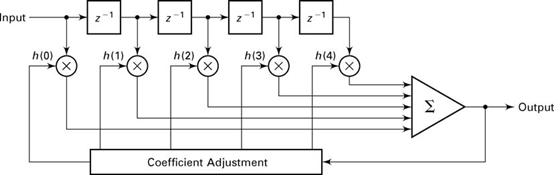

**解答**：

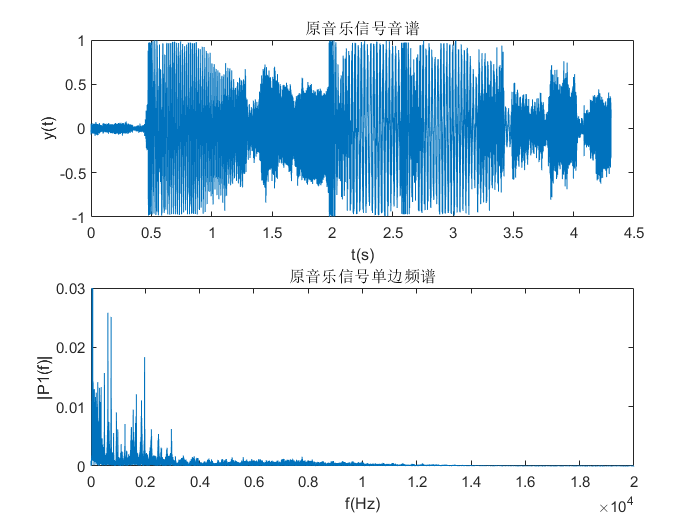

clc;
clear;
close all;
%读取音乐信号并画出音谱和频谱
filename='Justin Bieber.wav';
[y,Fs] = audioread(filename);%读取语音信号
[f,P1]=unilateral_fft(y,Fs);%自定义函数求语音信号单边谱
figure();
subplot(2,1,1);
t = [0:length(y)-1]/Fs;        % 时间
plot(t,y);
xlabel('t(s)');
ylabel('y(t)');
title('原音乐信号音谱');
subplot(2,1,2);
plot(f,P1);
xlabel('f(Hz)');
ylabel('|P1(f)|');
title('原音乐信号单边频谱');
axis([0 2e4 0 0.03]);

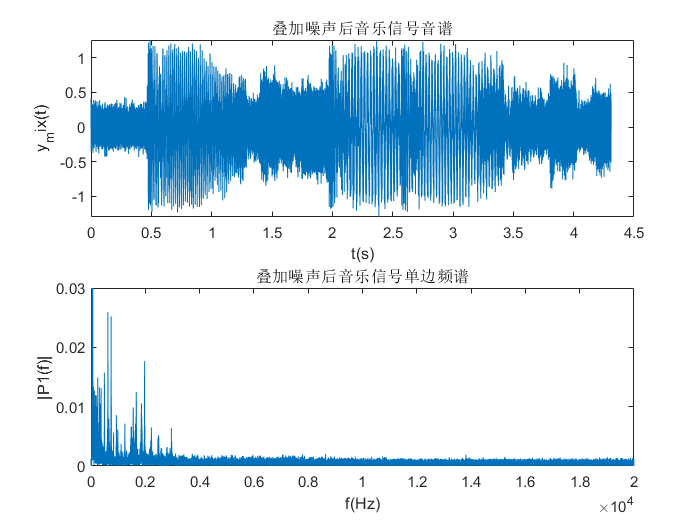


%读取音乐信号并画出音谱和频谱
y_mix = awgn(y,10,'measured');  % 添加高斯白噪声后的信号
[f_mix,P1_mix]=unilateral_fft(y_mix,Fs);%自定义函数求语音信号单边谱
figure();
subplot(2,1,1);
plot(t,y_mix);
xlabel('t(s)');
ylabel('y_mix(t)');
title('叠加噪声后音乐信号音谱');
subplot(2,1,2);
plot(f_mix,P1_mix);
xlabel('f(Hz)');
ylabel('|P1(f)|');
title('叠加噪声后音乐信号单边频谱');
axis([0 2e4 0 0.03]);

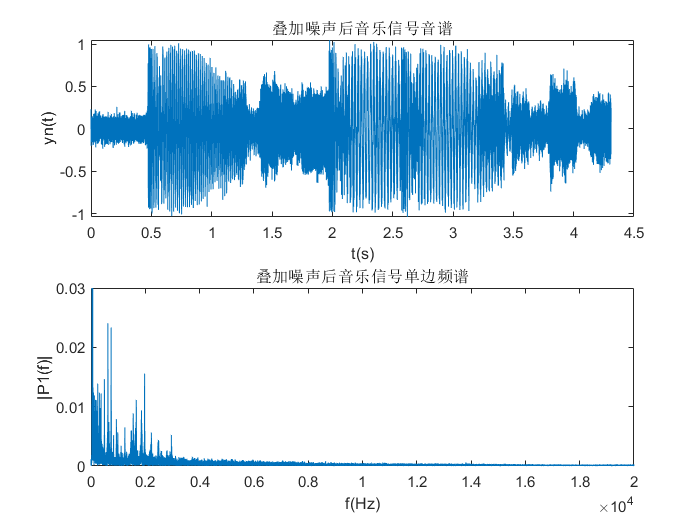


%LMS滤波
L = 5;     % 滤波器阶数
Mu = 0.05;   % μ的范围为0到1
xn = y_mix;     % 输入信号
dn = y;     % 期望信号
[yn, W] = LMS(xn,dn,L,Mu);

%滤波后音乐信号的音谱和频谱
[fn,P1_n]=unilateral_fft(yn,Fs);%自定义函数求语音信号单边谱
figure();
subplot(2,1,1);
plot(t,yn);
xlabel('t(s)');
ylabel('yn(t)');
title('叠加噪声后音乐信号音谱');
subplot(2,1,2);
plot(fn,P1_n);
xlabel('f(Hz)');
ylabel('|P1(f)|');
title('叠加噪声后音乐信号单边频谱');
axis([0 2e4 0 0.03]);

function [f,P1]=unilateral_fft(y,Fs)%fft的单边谱
    %f为对应频率点
    %P1为单边谱幅度
    %y为输入的语音信号
    %Fs为语音信号采样频率
    L=length(y);
    yw=fft(y);
    P2 = abs(yw/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
end

function [yn,W]=LMS(xn,dn,M,mu) %LMS滤波
    itr = length(xn);
    en = zeros(itr,1);             % 误差序列,en(k)表示第k次迭代时预期输出与实际输入的误差
    W  = zeros(M,itr);             % 每一行代表一个加权参量,每一列代表-次迭代,初始为0
    % 迭代计算
    for k = M:itr                  % 第k次迭代
        x = xn(k:-1:k-M+1);        % 滤波器M个抽头的输入
        y = W(:,k-1).' * x;        % 滤波器的输出
        en(k) = dn(k) - y ;        % 第k次迭代的误差
        % 滤波器权值计算的迭代式
        W(:,k) = W(:,k-1) + 2*mu*en(k)*x;
    end
    % 求最优时滤波器的输出序列  r如果没有yn返回参数可以不要下面的
    yn = zeros(size(xn)); % inf 是无穷大的意思
    for k = M:length(xn)
        x = xn(k:-1:k-M+1);
        yn(k) = W(:,end).'* x;%用最后得到的最佳估计得到输出
    end
end